# **Week 9: Machine learning basics**

**(live script created by E. Mika Diamanti on July 24th 2025; contact: emdiamanti@princeton edu)**

 What we do all the time in neuroscience (and other fields actually), is to use data to model a numerical response.

The topics covered are:

- what are (some of) the main types of -parametric- models -regression, classification- 

- what is the standard machine learning workflow

- how to evaluate the performance of the models 

Check this out for a quick Intro: [https://github.com/MathWorks-Teaching-Resources/Machine-Learning-for-Regression](https://github.com/MathWorks-Teaching-Resources/Machine-Learning-for-Regression)

Download code and open 'MachineLearningIntro.mlx'.

### Linear regression

- the response (or dependent variable) is a continous variable

- The predictors (or features, or independent variables) can be either continous or discrete. They form the 'feature matrix', where each column corresponds to one predictor.

Let's try to a fit a linear regression model ourselves!

load carsmall

% use as predictors the weight, horsepower and acceleration to predict MPG,
% with a linear regression model

% extract the model's coefficients

% plot the model


Note that you may also use non-numerical arrays as predictors

Remove `Acceleration` from the model, and try improving the model by adding the predictor variable `Model_Year`. First define `Model_Year` as a categorical variable.

But you cannot concatenate a numeric array, like the Weight with a categorical array.

Solution: store all variables in a [ table](https://www.mathworks.com/help/matlab/ref/table.html). 

tbl = table(Weight,Acceleration,Model_Year,MPG, ...
       'VariableNames',{'Weight','Acceleration','Model_Year','MPG'});

% now call fitlm with first input the table, and second input the
% formula of a model that uses weight and acceleration to predict MPG.


Using the 'modelSpec' input, to specify the model type  (eg. 'linear', 'quadratic', 'interactions')

lm2 = fitlm(tbl,'linear') % that's the default

Compare to the 'quadratic' or the 'interactions' models

### Logistic Regression for classification

You can model binomial distributions (that is variables that can take one out of two outcomes, example true vs. false) using a generalized regression model with the link function 'logit' ($f\left(\mu \right)=\;\frac{\log \left(\mu \right)}{\log \left(1-\mu \right)}$)

*The link function defines the relationship *f*(*μ*) = *X***b* between the mean response *μ* and the linear combination of predictors *X***b*

load patients
% create a table with the variables age, weight, gender, smoker 


% specify the model that predicts smoking status from the other 3
% variables. Add a third input that specifies the 'Distribution'='binomial'

%modelSpec = 
%mdl = fitglm(tbl,modelSpec,)

% alternatively instead of creating a table you can use the syntax mdl =
% fitglm(X,y), where X is a matix of predictors and y is the response.

the main workflow for machine learning:

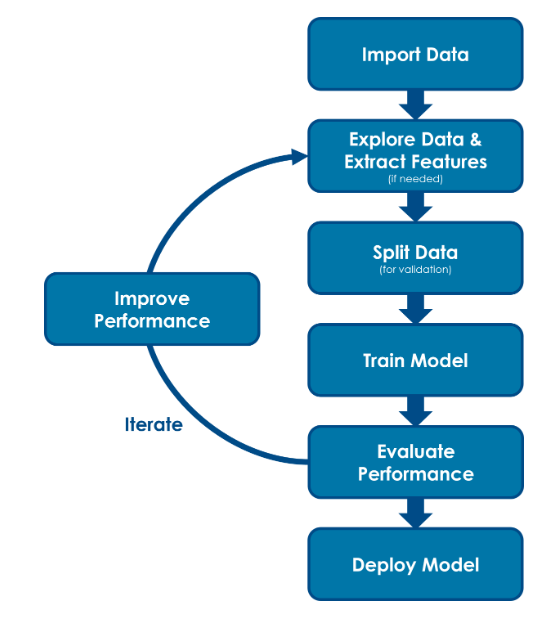

### Cross-validation to 'train' and 'test' models

To evaluate performance, we use measures of model performance on test data, that is data that were not used to train (aka 'fit') the model.

% first, define the predictors
load patients
X1 = Diastolic;
X2 = categorical(Gender);
X3 = Systolic;
y = Smoker;

% now use cvpartition() to partition the data into train and test sets
% using 5-fold xvalidation.
CV = cvpartition(numel(y),KFold= 5); % note c is an object!
for iF = 1:CV.NumTestSets
    testIdx = CV.test(iF);

    % here define train and test sets

    % define and train model
    XYtrain = table(X1train,X2train,X3train,ytrain, ...
    'VariableNames',{'Diastolic','Gender','Systolic','Smoker'});
   

    % test model
    Xtest = table(X1test,X2test,X3test, ...
    'VariableNames',{'Diastolic','Gender','Systolic'});
    
    % estimate models's missclassification error
    
end

%mean error across folds



% or, use the MATLAB inbuilt function crossval() to estimate the
% missclasification error ('mcr'). By default crossval will perform 10-fold
% xvalidation.
% syntax: err = crossval(criterion,X,y,'Predfun',predfun)

err = crossval('mcr',X1,X2,X3,y,'Predfun',@classf)

%function pred = classf(X1train,X2train,X3train,ytrain,X1test,X2test,X3test)
% same as above, but wrapped inside a function

%define Xtrain & Ytrain

%define Xtest

% define and train the model

%test the model

%end



  Then you can perform model comparisons based on these numbers. For example, 

- how much does the loss differ, when you omit the predictor gender?

- how much does the loss differ when you allow all the pairwise interactions between the variables age, weight, and sex. 

%specify modelSpec for 2. here